# Homework #1: Programming and Interpolation

## Problem 1 (30 points) 

Complete the MATLAB onramp at [https://matlabacademy.mathworks.com/](https://matlabacademy.mathworks.com/). It may take up to three hours to complete. You are strongly encouraged to complete it before or during the first week of labs. When you're nonwhite_found, please make a image of your completion certificate and insert it below. 

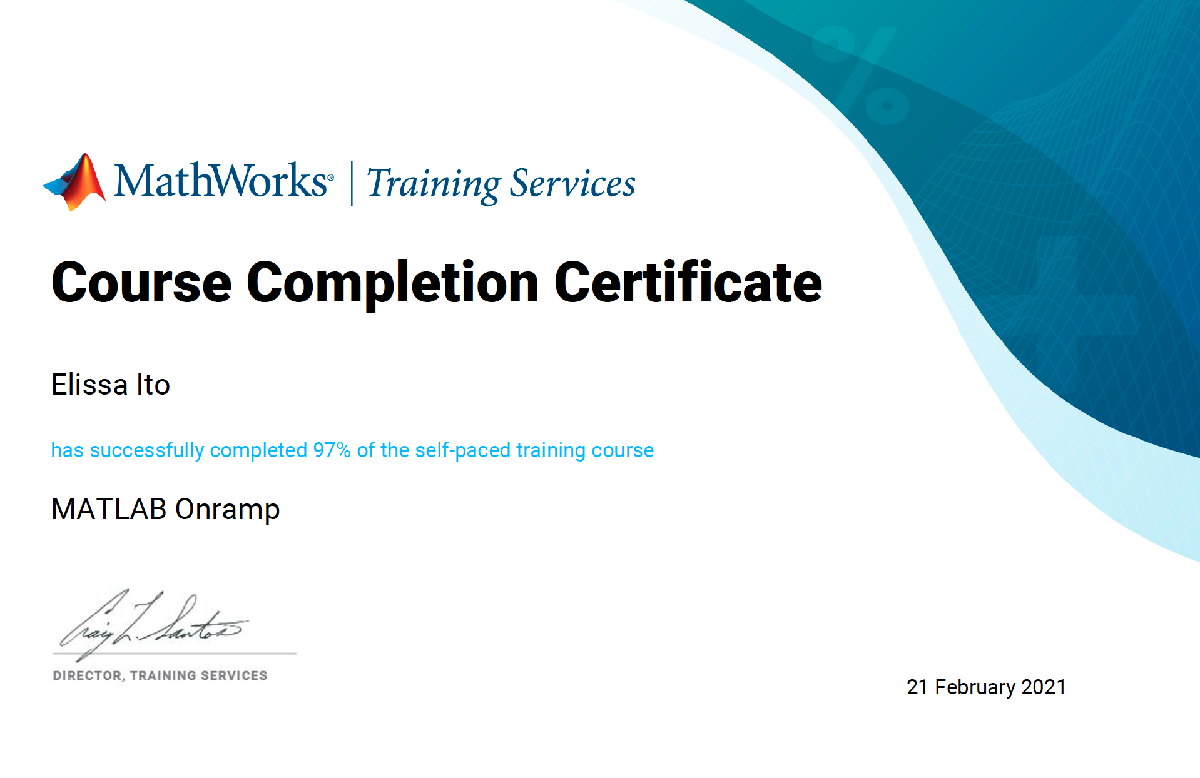

## Problem 2 (25 points)

Consider the series 


$$x=\frac{1}{2}+\frac{1}{4}+\frac{1}{8}+\frac{1}{16}+\cdots$$


a) (5 points) Compute and sum the first 20 terms.  Save the answer in a variable named "x_part_a"

% Here's some code to get you started
format long % so that we can see 16 digits
% Your code here:
sum = 0;
for ix = 1:20
    sum = sum + 1/(power(2,ix));
end
x_part_a = sum

x_part_a =    0.999999046325684


b) (5 points) Compute and sum all the terms up to but not including the first term that is less than ${10}^{-15}$.  Save the answer in a variable named "x_part_b".


% insert your code below
ix = 1;
sum = 0;
while 1/(power(2,ix)) > power(10,-15)
    sum = sum + 1/(power(2,ix));
    ix = ix + 1;
end
x_part_b = sum

x_part_b =    0.999999999999998


c) (5 points) Consider the code below which plots the size of terms in the series we've been exploring here.  Why does the semi-log plot stop at a value of n somewhere between 1000 and 1200?  Explain in a comment below.  

% Here is code for you to inspect
realmin

ans =     2.225073858507201e-308


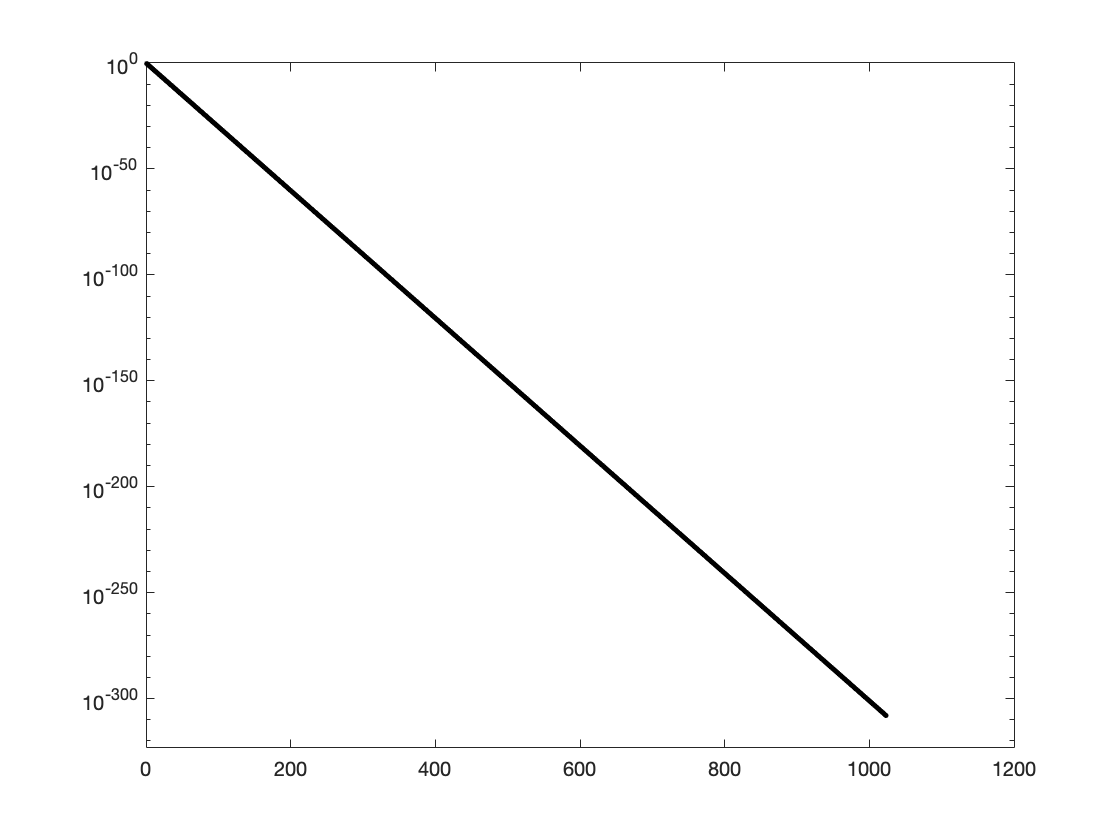

n=1:1200;
close all
semilogy(n,1./(2.^n),'k.')

% Your comment here please: 
%   the smallest positive normalized floating-point number is approximately
%   2.225e-308. At n=1000, the term is 1/(2^1000) which is approximately
%   9.33e-302 which is larger than the smallest floating-point number and
%   at n=1200, the term is 1/(2^1200) which is approximately
%   5.88e-362, which is smaller than the smallest possible floating-point
%   number. Thus, the semi-log plot stops between n=1000 and n=1200 (around
%   n = 1022)

d) (5 points) This problem expands further on the issues with the plot in part (c).  Below is some code that forms a 1x1200 matrix called y_axis_position.  Write a bit of code below to display the largest value of n for which the value of y_axis_position(n) is not equal to -Inf,  Put your answer in a variable named **n_max.**   

y_axis_position=log(1./(2.^n));
n = 1;
% Put your code here
while y_axis_position(n) ~= -inf
    n = n+1;
end
n_max = n

n_max =         1024


e) (5 points) Consider the code below.  Make a comment on the output from the last line.  Why is this result emerging as logical 1 (true) even though $\frac{1}{2^{55} }>0$?   

% Here is code for you to inspect
eps

ans =      2.220446049250313e-16


n=55;
%disp(sum(1./2.^(1:(n-1)))==sum(1./2.^(1:(n-1)))+1/2^n)
% Your comment here please: 
%   eps, the floating-point relative accuracy is the smallest difference
%   that two floating-points can have for Matlab to determine as non-equal.
%   Since 1/2^55 - 1/2^54 is approximately 2.77e-17 (smaller than eps),
%   Matlab determines the two sums as equal.

## Problem 3 (30 points) 

In a paper [1] published by one of our Mechanical Engineering faculty, Prof. Ellen Roche, a system was analyzed that could serve to deliver medicines directly into targetted tissues. 

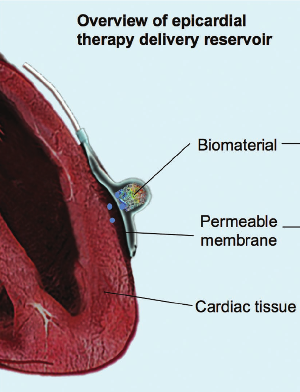  

[[1]](#_ftnref1) Shirazi, R. N., S. Islam, F.M. Weafer, W. Whyte, C.E. Varela, A. Villanyi, W. Ronan, P McHugh, and E. Roche, 2019, “Multiscale Experimental and Computational Modeling Approaches to Characterize Therapy Delivery to the Heart from Implantable Epicardial Biomaterial Reservoir.” Advanced Healthcare Materials, *8*, 1900228.

In that paper was the graph below of the maximum penetration of a drug into cardiac tissue as a function of time.

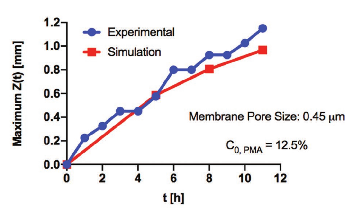

Let’s say that the tabulated values in the code block below represent the simulation results from that paper.

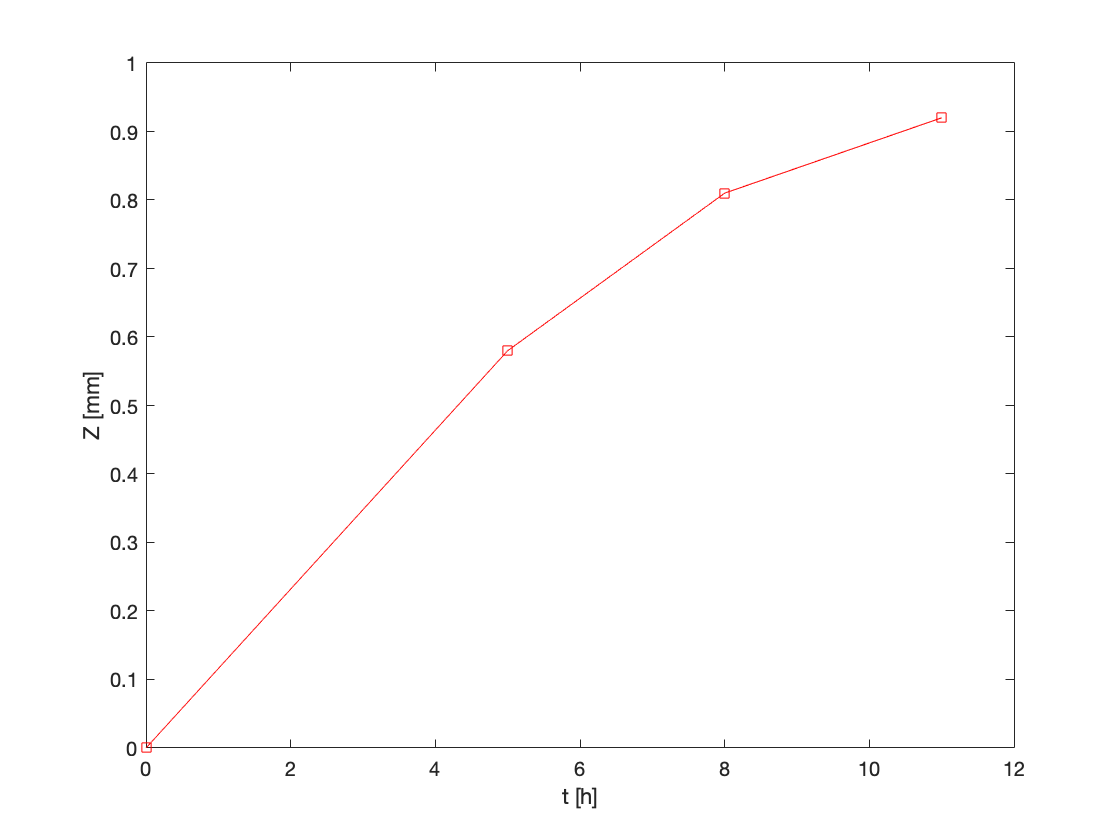

clear
t=[0 5 8 11]; % in hours
Z=[0 0.58 0.81 0.92]; % in mm
plot(t,Z,'rs-')
xlabel('t [h]')
ylabel('Z [mm]')

a) (6 points) Use piecewise-constant left-endpoint interpolation to predict the penetration of the drug (Z) at a time of 5.7 hours.

% Here's the value at which we "query" the interpolation procedure:
tq_a=5.7;
% Put your work below, and store the interpolated penetration in a variable Z_a
ix = 1;
t_i = t(1);
while t_i < tq_a
    ix = ix+1;
    t_i = t(ix);
end
ix = ix - 1;
t_i = t(ix);
Z_a = Z(ix)

Z_a =    0.580000000000000


b) (6 points) Use linear interpolation to predict the penetration of the drug (Z) at a time of 5.7 hours.

% The query value is the same
tq_b=tq_a;
% Put your work below, and store the interpolated penetration in a variable Z_b
ix = 1;
t_i = t(1);
while t_i < tq_a
    ix = ix+1;
    t_i = t(ix);
end
ix = ix - 1;
t_i = t(ix);
Z_b = Z(ix) + ((Z(ix+1)-Z(ix))/(t(ix+1)-t(ix))).*(tq_a-t(ix))

Z_b =    0.633666666666667


c) (5 points) Recreate the plot provided in the question and identify the interpolated point you found in part (a) with a red " x " and the interpolated point you found in part (b) with a green " o ". Also insert on the plot a vertical green dashed line from the x axis up to the interpolated point you found in part (b).

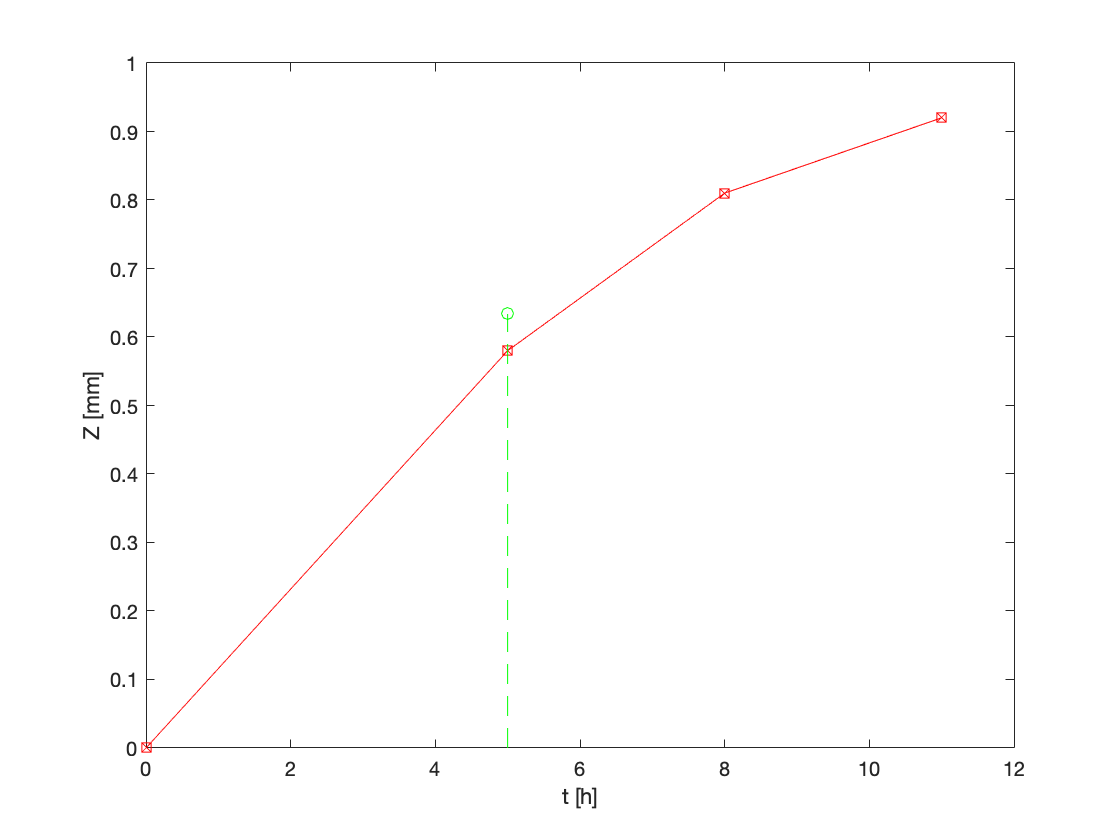

% Put your work below
hold on
plot(t,Z,"rx")
plot(t_i,Z_b,"go")
plot([t_i, t_i], [0, Z_b], "g--")

d) (4 points) Assume that the true underlying function for the penetration is given by the function Z`_true` below. Calculate the interpolation error of piecewise-constant left-endpoint interpolation at time of 5.7 hours and save it in variable `err_const`. Calculate the interpolation error of linear interpolation at a time of 5.7 hours and save it in variable `err_lin`. 

% ------------------------------------------------
% Do not modify
Z_true=@(gc) interp1(t,Z,gc,'spline');
tp=linspace(t(1),t(end));
plot(tp, Z_true(tp))
xlabel('t [h]')
ylabel('Z [mm]')
%-------------------------------------------------

% Put your work below
t_q = 5.7

t_q =    5.700000000000000


err_const = Z_true(t_q) - Z_a

err_const =    0.063042477272727


err_lin = Z_true(t_q) - Z_b

err_lin =    0.009375810606061


e) (1 point) Comment on your results from part d.

% Put your comment here:
%   The error for linear interpolation is much smaller than the error for
%   piecewise-constant left endpoint interpolation.


f) (5 points) At some point, the penetration will be 0.85 mm. Use linear interpolation to estimate the time at which this will occur.  Place the value in a variable named "time_for_Z_pt85"

% Here's the value at which we "query" the interpolation procedure
Zq_f=0.85;
% Put your work below, and set the interpolated temperature output to Tq_e
ix = 1;
Z_i = Z(1);
while Z_i < Zq_f
    ix = ix+1;
    Z_i = Z(ix);
end
ix = ix - 1;
Z_i = Z(ix);
time_for_Z_pt85 = t(ix)

time_for_Z_pt85 =      8


g) (3 points) On the plot you created for part (c) identify the point interpolated in part (e) with both a black triangle and a horizontal black dashed line from the y axis across to that point.

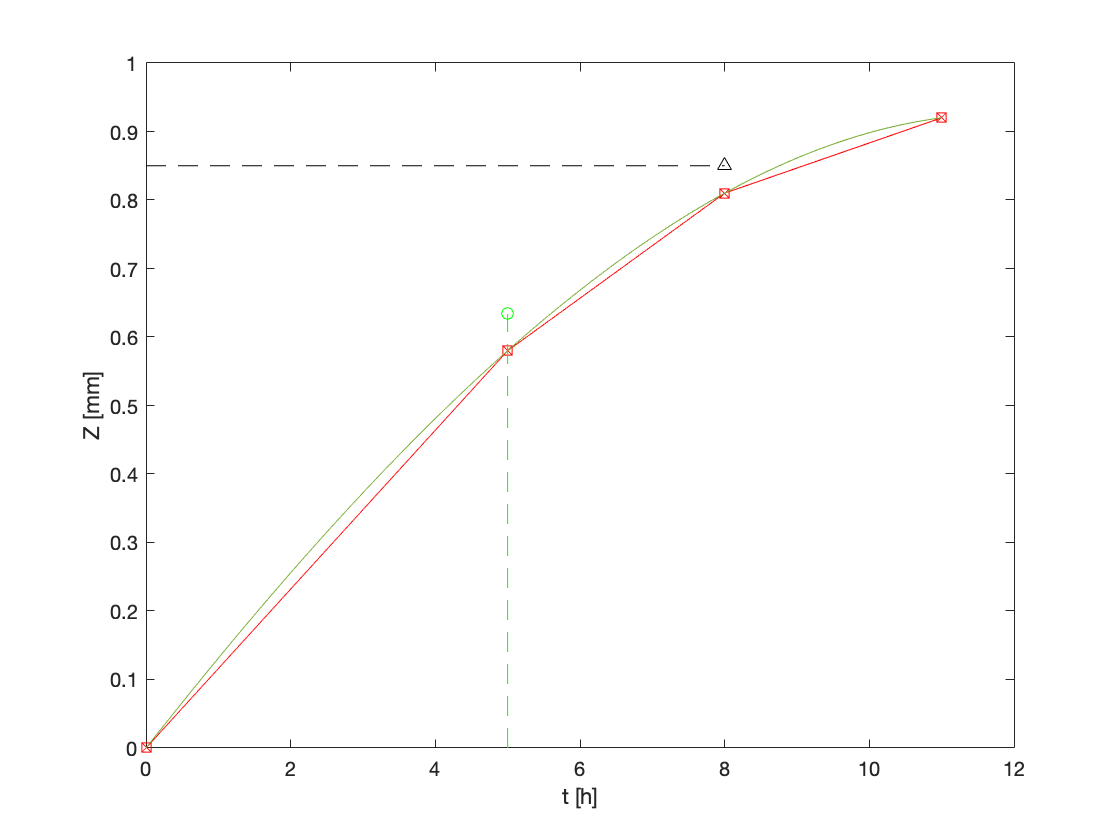

% Put your work below
plot(time_for_Z_pt85,Zq_f,"k^")
plot([0, time_for_Z_pt85], [Zq_f, Zq_f], "k--")

## Problem 4 (15 points) 

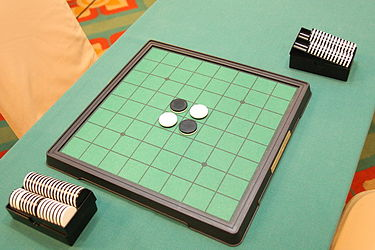

image from en.wikipedia.org/wiki/Reversi

NOTE: If you are new to programming, you may find this problem rather hard.  If you're finding it too difficult to code at this stage, try writing instructions in natural language instead.  Just write step-by-step instructions as if the person reading them needed a rather explicit description.  The graders will give substantial credit for any effort that demonstrates good computational thinking even if proficiency in coding isn't demonstrated yet.  

There is a game called Reversi in which players take turns placing disks onto a square grid.  The starting state of the board is shown above.  There are sixty-four identical disks which are dark on one side and light on the other.   Players take turns placing disks on the board with their assigned color facing up. During a play, any disks of the opponent's color that are in a straight line and bounded by the disk just placed and another disk of  the current player's color are turned over to the current player's color. The object of the game is to have the majority of disks turned to display your color when the last playable empty square is filled. 

In MATLAB, we can represent the state of the board at each step of the game play as an 8 by 8 array with zeros indicating unfilled locations, 1s representing black discs, and 2s representing white discs.  Let’s use the variable name `state.``  T`he code below sets up and displays the initial state:

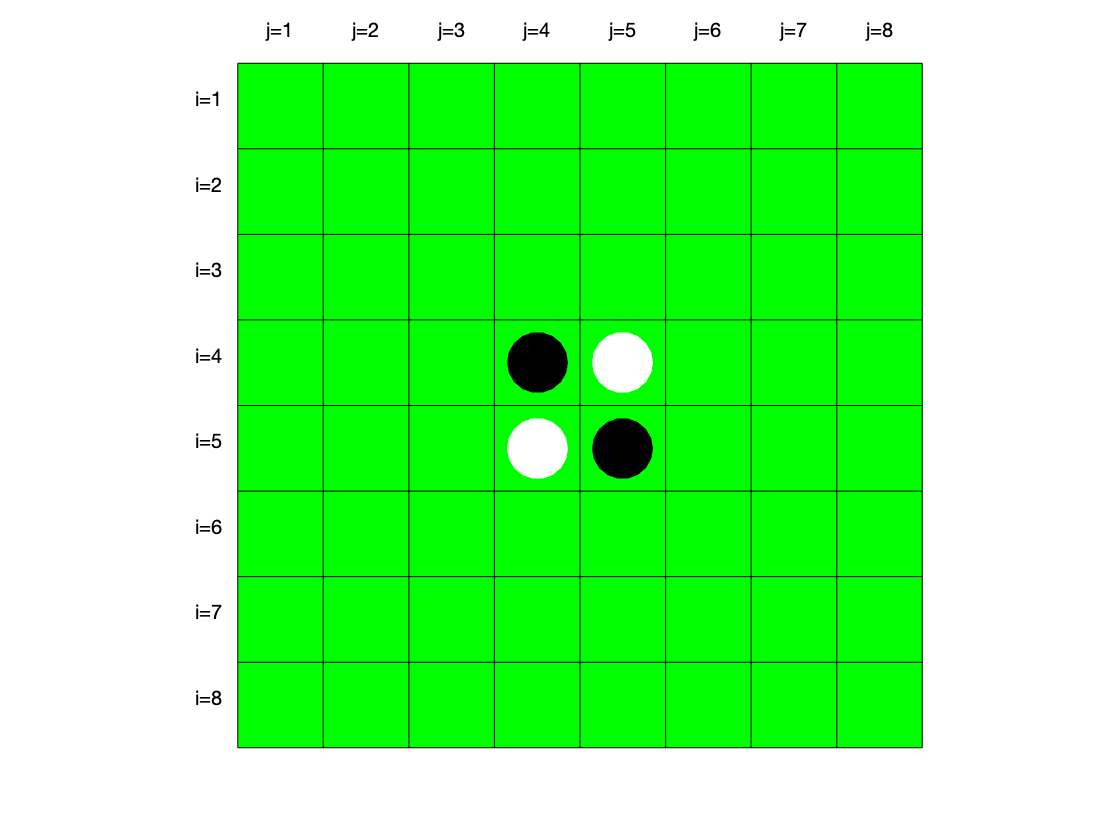

close all
state=[0 0 0 0 0 0 0 0; 
       0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0;
       0 0 0 1 2 0 0 0;
       0 0 0 2 1 0 0 0;
       0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0];
plot_board(state)

a) (10 points) Write a short segment of code that, given a data structure `state` and given a proposed play by the dark player, will change the data structure `state` consistently with the rules of the game. You may assume that the proposed move is legal, which means that there exists at least one straight (horizontal, vertical, or diagonal) occupied line between the new piece and another dark piece, with one or more contiguous light pieces between them.  When that play is made, the light pieces that are surrounded by the new dark piece and an existing dark piece will flip (and therefore change color from light to dark).   In this MATLAB implementation, the proposed move is encoded as a pair of integers stored in a 1 x 2 vector named `dark_move`.       

% EXAMPLE 1
% dark_move=[3,5];
% state=[0 0 0 0 0 0 0 0; 
%        0 0 0 0 0 0 0 0;
%        0 0 0 0 0 0 0 0;
%        0 0 0 1 2 0 0 0;
%        0 0 0 2 1 0 0 0;
%        0 0 0 0 0 0 0 0;
%        0 0 0 0 0 0 0 0;
%        0 0 0 0 0 0 0 0];
% state=
% NOTE: For the example provided here, state should become 
%     [0 0 0 0 0 0 0 0; 
%      0 0 0 0 0 0 0 0;
%      0 0 0 0 1 0 0 0;
%      0 0 0 1 1 0 0 0;
%      0 0 0 2 1 0 0 0;
%      0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0];

%EXAMPLE 2

dark_move=[1,5];
state=[0 0 0 0 0 0 0 0; 
       0 0 0 0 2 0 0 0;
       0 0 0 0 2 0 0 0;
       0 0 0 1 2 0 0 0;
       0 0 0 2 1 2 0 0;
       0 0 2 1 1 0 0 0;
       0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0];

% Place you code here
% For the example provided here, state should become
%       [0 0 0 0 1 0 0 0; 
%        0 0 0 0 1 0 0 0;
%        0 0 0 0 1 0 0 0;
%        0 0 0 1 1 0 0 0;
%        0 0 0 2 1 2 0 0;
%        0 0 2 1 1 0 0 0;
%        0 0 0 0 0 0 0 0;
%        0 0 0 0 0 0 0 0];

%EXAMPLE 3
%dark_move=[1,1];
%state=[0,2,2,1;
%        0,2,0,0;
%        0,0,1,0;
%        0,0,0,0];
% Place you code here
% 0=empty; 1=black; 2=white;
% PLAN:
% turn "move" block black
% for all surrounding directions:
%   if consecutive is white:
%       while next one over is white and not at edge of board:
%           check next one over
%       if at edge of board and is white:
%           do nothing
%       elif nonwhite is empty:
%           do nothing
%       elif nonwhite is black:
%           turn all travered white tiles black
%   else:
%       do nothing
state(dark_move(1),dark_move(2)) = 1;
board_size = size(state);
row = dark_move(1);
col  = dark_move(2);
nonwhite_found = 0;
go = 0;
start_edge = at_edge(board_size,row,col);
%DIAGONALLY UPPER LEFT
if start_edge && (row==1 || col==1)
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row-1,col-1)
    if state(row-1,col-1)~=2
        nonwhite_found = 1;
    else
        row = row-1;
        col = col-1;
    end
end

if ~nonwhite_found
    if ~(row==1 || col==1)
        if state(row-1,col-1)==1
            go = 1;
        end
    end
end

if go
    while row~=dark_move(1) && col~=dark_move(2)
        state(row,col)=1;
        row = row+1;
        col = col+1;
    end
end
nonwhite_found = 0;
go = 0;
%STRAIGHT LEFT
if start_edge && (col==1)
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row,col-1)
    if state(row,col-1)~=2
        nonwhite_found = 1;
    else
        col = col-1;
    end
end
if ~nonwhite_found
    if ~(col==1)
        if state(row,col-1)==1
            go = 1;
        end
    end
end
if go
    while col~=dark_move(2)
        state(row,col)=1;
        col = col+1;
    end
end
nonwhite_found = 0;
go = 0;
%DIAGONALLY LOWER LEFT
if start_edge && (row==board_size(1) || col==1)
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row+1,col-1)
    if state(row+1,col-1)~=2
        nonwhite_found = 1;
    else
        row = row+1;
        col = col-1;
    end
end
if ~nonwhite_found
    if ~(row==board_size(1) || col==1)
        if state(row+1,col-1)==1
            go = 1;
        end
    end
end
if go
    while row~=dark_move(1) && col~=dark_move(2)
        state(row,col)=1;
        row = row-1;
        col = col+1;
    end
end
nonwhite_found = 0;
go = 0;
%STRAIGHT UP
if start_edge && (row==1)
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row-1,col)
    if state(row-1,col)~=2
        nonwhite_found = 1;
    else
        row = row-1;
    end
end
if ~nonwhite_found
    if ~(row==1)
        if state(row-1,col)==1
            go = 1;
        end
    end
end
if go
    while row~=dark_move(1)
        state(row,col)=1;
        row = row+1;
    end
end
nonwhite_found = 0;
go = 0;
%STRAIGHT DOWN
if start_edge && (row==board_size(1))
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row+1,col)
    if state(row+1,col)~=2
        nonwhite_found = 1;
    else
        row = row+1;
    end
end
if ~nonwhite_found
    if ~(row==board_size(1))
        if state(row+1,col)==1
            go = 1;
        end
    end
end
if go
    while row~=dark_move(1)
        state(row,col)=1;
        row = row-1;
    end
end
nonwhite_found = 0;
go = 0;
%DIAGONALLY UPPER RIGHT
if start_edge && (row==1 || col==board_size(2))
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row-1,col+1)
    if state(row-1,col+1)~=2
        nonwhite_found = 1;
    else
        row = row-1;
        col = col+1;
    end
end
if ~nonwhite_found
    if ~(row==1 || col==board_size(2))
        if state(row-1,col+1)==1
            go = 1;
        end
    end
end
if go
    while col~=dark_move(2)
        state(row,col)=1;
        row = row+1;
        col = col-1;
    end
end
nonwhite_found = 0;
go = 0;
%STRAIGHT RIGHT
if start_edge && (col==board_size(2))
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row,col+1)
    if state(row,col+1)~=2
        nonwhite_found = 1;
    else
        col = col+1;
    end
end
if ~nonwhite_found
    if ~(col==board_size(2))
        if state(row,col+1)==1
            go = 1;
        end
    end
end

if go
    while col~=dark_move(2)
        state(row,col)=1;
        col = col-1;
    end
end
nonwhite_found = 0;
%DIAGONALLY LOWER RIGHT
if start_edge && (row==board_size(1) || col==board_size(2))
    nonwhite_found = 1;
end
while (~at_edge(board_size,row,col)||(start_edge && row == dark_move(1) && col == dark_move(2))) && ~nonwhite_found && ~at_edge(board_size,row-1,col-1)
    if state(row+1,col+1)~=2
        nonwhite_found = 1;
    else
        row = row+1;
        col = col+1;
    end
end
if ~nonwhite_found
    if ~(row==board_size(1) || col==board_size(2))
        if state(row+1,col+1)==1
            go = 1;
        end
    end
end
if go
    while row~=dark_move(1) && col~=dark_move(2)
        state(row,col)=1;
        row = row-1;
        col = col-1;
    end
end
nonwhite_found = 0;
go = 0;
state

state =      0     0     0     0     1     0     0     0
     0     0     0     0     2     0     0     0
     0     0     0     0     2     0     0     0
     0     0     0     1     2     0     0     0
     0     0     0     2     1     2     0     0
     0     0     2     1     1     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


b) (5 points) Write a short segment of code that, for a given state of the game board encoded by the data structure `state`, returns the fraction of the pieces that are dark in a variable named  `fraction_dark`.  

state=[0 0 0 0 1 0 0 0; 
       0 0 0 0 1 0 0 0;
       0 0 0 0 1 0 0 0;
       0 0 0 1 1 0 0 0;
       0 0 0 2 1 2 2 2;
       0 0 2 1 1 0 0 0;
       0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0];
% Place you code here
board_size = size(state);
dark_sum = 0;
light_sum = 0;
for row = 1:board_size(1)
    for col = 1:board_size(2)
        if state(row,col)==1
            dark_sum = dark_sum + 1;
        else
           if state(row,col)==2
                light_sum = light_sum + 1;
           end
        end
    end
end
fraction_dark = dark_sum./(dark_sum+light_sum)

fraction_dark =    0.615384615384615


% For the example provided above, fraction_dark will be 0.6154



function plot_board(state)
% This function makes a graphical representation of the game board
% variable state is an 8x8 matrix of 0s, 1s and 2s
hold on
% Make a green board that is initially empty
for i=1:8
    for j=1:8
        fill([0 1 1 0 0]+i-0.5,[0 0 1 1 0]+j-1.5,'g')
    end
end
% Make some labels for the row number
for i=1:8
    text(0,8-i,['i=',num2str(i)],'VerticalAlignment','baseline')
end
% Make some labels for the column number
for j=1:8
    text(j,7.9,['j=',num2str(j)],'HorizontalAlignment','center')
end
% Fill in the colored game pieces
for i=1:8
    for j=1:8
        if state(i,j)==1
            plot(j,8-i,'o',...
            'MarkerFaceColor',[0 0 0],...
            'MarkerEdgeColor',[0 0 0],'MarkerSize',30)
        end
        if state(i,j)==2 
            plot(j,8-i,'o',...
            'MarkerFaceColor',[1 1 1],...
            'MarkerEdgeColor',[1 1 1],'MarkerSize',30)
        end 
    end
end
axis equal
axis off
end

function edgeness = at_edge(board_size, row, col)
    if row==1|row==board_size(1)|col==1|col==board_size(2)
        edgeness = 1;
    else
        edgeness = 0;
    end
end